# Cantilever Equations of Motion (Lumped parameter)

Derives the equations of motion for a (nonuniform) lumped parameter cantilever made up of multiple sections. We may taper the beam by changing the height of each section.

% Options
sympref('AbbreviateOutput', false);
N = 10; % number of sections

% Parameters of uniform beam (in SI base units)
params = struct;
vecs = struct;   % for vector parameters
params.g = 9.81;           % gravity
params.L = 1;              % length
params.b = 2e-3;          % width/breadth
params.E = 200e9;          % Young's modulus, Mild steel
params.rho = 7850;         % Density, Mild steel
params.c = 1e-3;              % damping coefficients 

% height - NB: set to vector to shape beam if desired:
% vecs.h = 2e-3 * ones(N,1);        % uniform beam
vecs.h = 2e-3 * linspace(1.5, 0.5, N)';        % tapered beam

% Intermediate calculations, for stiffnesses, inertias, etc
params.dL = params.L/N;                % section length
vecs.m = params.rho*vecs.h*params.b*params.dL;          % section masses
vecs.Ix = params.b*vecs.h.^3 / 12;        % 2nd moment of area (for rectangular beam)
vecs.K_d = 3*params.E*vecs.Ix / params.dL;       % stiffness
vecs.dJ = vecs.m.*(params.dL^2+vecs.h.^2)/12;  % section moments of inertia (rectangular)

% Parameters
syms m [N 1];
syms K_d [N 1];
syms dL;
syms J [N 1];
syms g;
syms c;

% coordinates
syms x [N 1];
syms v [N 1];
syms a [N 1];
syms d [N 1];
syms o [N 1];
syms t;

% symfuns
syms q(t) [N 1];

## Model building, to get equations of motion

NB: Euler-Bernoulli type assumptions - no shear force, but we retain rotational inertia (EB ignores it)

% Kinematics (the first two set the boundary condition, i.e. x(0) = v(0) = 0)
% Linearised kinematics: Assume small angles (makes L quadratic, EOM linear, if springs are linear)
d(1) = x(1)/dL;
o(1) = v(1)/dL;
for ii=2:N
    d(ii) = (x(ii) - x(ii-1))/dL;   % small angle approx for sin
    o(ii) = (v(ii) - v(ii-1))/dL;   % small angle approx
end

% Kinetic energy
T = 1/2*m(1)*v(1)^2 + 1/2*J(1)*o(1)^2;
for ii=2:N
    T = T + 1/2*m(ii)*(v(ii)+v(ii-1))^2 + 1/2*J(ii)*o(ii)^2; 
end

% Nonlinear spring 'stiffening' constant
% k_nonlin = 1e6;       % nonlinear springs (stiffer for large deflection if positive)
k_nonlin = 0.0;       % linear springs

% Potential energy (torsional springs + gravity)
V = 1/2 * m(1)*g*x(1);      % gravity
V = V + 1/2*K_d(1)*d(1)^2 + 1/4*k_nonlin*K_d(1)*d(1)^4;      % spring P.E.
for ii=1:N-1
    V = V + 1/2* m(ii)*g*(x(ii)+x(ii+1));       % gravity
    V = V + 1/2*K_d(ii)*(d(ii+1)-d(ii))^2 + 1/4*k_nonlin*K_d(ii)*(d(ii+1)-d(ii))^4;    % spring P.E.
end

% Lagrangian
L = simplify(T - V)

% Generalised forces (for damping terms on angular velocities)
Q = c*o;

% Take the functional derivative to get EOM (Euler-Lagrange / Hamilton's principle)
L = subs(L, [x v], [q diff(q,t)]);
eom_lhs = functionalDerivative(L, q) - Q;    % == 0, not displayed as it makes the live editor SLOW

## Solve for equilibrium deflection of the beam under gravity

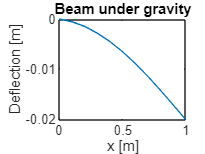

% substitute back variables for functions for next part
eom_vars = subs(eom_lhs, [diff(q,2) diff(q,t) q], [a,v,x]);
eom_vars = eom_vars(0);      % evaluate at "t=0" (slight hack, t not in expression but it converts symfun back to sym)

% now substitute v=0, a=0 along beam and solve for 'x' to find equilibrium
eom_eq = subs(eom_vars, [v, a], [zeros(N,1), zeros(N,1)]);
eom_eq = subs(eom_eq, params);        % this works for scalar (not vector) params only
eom_eq = subs(eom_eq, m, vecs.m);
eom_eq = subs(eom_eq, K_d, vecs.K_d);
fun = matlabFunction(eom_eq, 'Vars', {x});
opts = optimset('Display','off');
eq_point = fsolve(fun,zeros(N,1),opts);

% Plot the deflection of the beam under gravity
figure; cla; box on;
plot(params.dL*[0:N], [0; eq_point])
title('Beam under gravity'); xlabel('x [m]'); ylabel('Deflection [m]')

## Get mass and stiffness matrices for the system

In this part, we express the equations of motion in the (linearised) second order matrix form $M\ddot{x}+C\dot{x}+Kx=G$

% We will linearise around the equilibrium point
x_lin = eq_point;
v_lin = zeros(N,1);

% M is Jacobian w.r.t. the accelerations, evaluated at equilibrium point
M = -jacobian(eom_vars, a);
M = subs(M, [x,v], [x_lin, v_lin])

% C is Jacobian w.r.t. velocities, evaluated at linearisation point
C = -jacobian(eom_vars, v);
C = subs(C, [x,v], [x_lin, v_lin])

$$C = \left(\begin{array}{cccccccccc} \frac{c}{\mathrm{dL}} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\frac{c}{\mathrm{dL}} & \frac{c}{\mathrm{dL}} \end{array}\right)$$

% K is the Jacobian w.r.t. positions, at linearisation point
K = -jacobian(eom_vars, x);
K = subs(K, [x,v], [x_lin, v_lin])

% Weight vector G is the constants, but the easiest way to get them is:
G = simplify(diff(eom_vars,g))*g

$$G = \left(\begin{array}{c} -g\,m_{1}\\ -g\,\left(\frac{m_{1}}{2}+\frac{m_{2}}{2}\right)\\ -g\,\left(\frac{m_{2}}{2}+\frac{m_{3}}{2}\right)\\ -g\,\left(\frac{m_{3}}{2}+\frac{m_{4}}{2}\right)\\ -g\,\left(\frac{m_{4}}{2}+\frac{m_{5}}{2}\right)\\ -g\,\left(\frac{m_{5}}{2}+\frac{m_{6}}{2}\right)\\ -g\,\left(\frac{m_{6}}{2}+\frac{m_{7}}{2}\right)\\ -g\,\left(\frac{m_{7}}{2}+\frac{m_{8}}{2}\right)\\ -g\,\left(\frac{m_{8}}{2}+\frac{m_{9}}{2}\right)\\ -\frac{g\,m_{9}}{2} \end{array}\right)$$

## Calculate mode shapes and frequencies

Here we calculate the vibration frequencies and corresponding modes of the cantilever system from $M\ddot{x} + Kx = 0$, for the specified beam

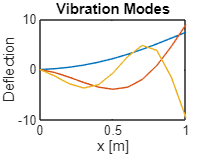

% Substitute into mass, stiffness, damping, G matrices
K_uf = subs(K, params);
K_uf = subs(K_uf, K_d, vecs.K_d);
K_uf = double(K_uf);
M_uf = subs(M, params);
M_uf = subs(M_uf, m, vecs.m);
M_uf = subs(M_uf, J, vecs.dJ);
M_uf = double(M_uf);
C_uf = subs(C, params);
G_uf = subs(G, params);
G_uf = subs(G_uf, m, vecs.m);

% Now get and plot the mode shapes
[V,D] = eigs(K_uf, M_uf, 3,'smallestabs');
figure; cla 
hold on; box on;
for k=1:3
    plot(params.dL*[0:N], [0;V(:,k)])
end
title('Vibration Modes'); xlabel('x [m]'); ylabel('Deflection')

% Calculate the corresponding characteristic frequencies (in Hz)
sqrt(diag(D)) / (2*pi)

ans =     2.5149
   10.3205
   25.7715


## Code Generate a simulink model to simulate the (linearised) system

% Form the right-hand side of the linearised (really, affine due to G!) system ODEs in state-space form
ode_rhs = [M_uf \ (G_uf - C_uf*v - K_uf*x);  v];
S = [v; x];
IC = strcat('zeros(', num2str(2*N) ,',1)');      % zero initial conditions 

% Generate simulink model
openLoopModel(ode_rhs, S, [], IC, 'cantilever');

Creating new Simulink model.
